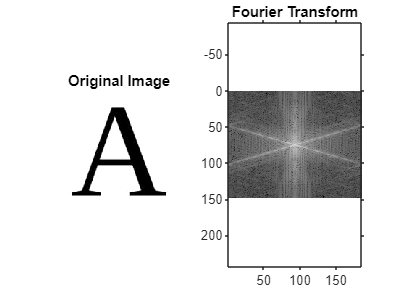

% Load the image
image = imread('A.jpg');

% Convert the image to grayscale if it's not already
if size(image, 3) == 3
    image = rgb2gray(image);
end

% Perform the Fourier Transform
f_transform = fft2(double(image));

% Shift the zero frequency component to the center
f_transform_shifted = fftshift(f_transform);

% Compute the magnitude of the Fourier Transform
magnitude = abs(f_transform_shifted);

% Display the original image
subplot(1, 2, 1);
imshow(image);
title('Original Image');

% Display the Fourier Transform
subplot(1, 2, 2);
imshow(log(1 + magnitude), []); % Use logarithmic scaling for better visualization
title('Fourier Transform');

% Show the images with proper axis labeling
colormap(gca, 'gray');
axis on;
axis equal;


% Optional:  can also save the magnitude image if needed
imwrite(log(1 + magnitude), 'fourier_transform_magnitude.jpg');

